**João Luiz de Castro - UFC**

clear all
close all
clc

DC motor especification:

Leq = 0.1;
Req = 0.2;
J = 1;
Baux = 0.1;
Ka = 1;

Matrix definition:

- A:

A = [-Req/2 0 0;
    Ka/J -Baux/J 0
    0 0 1];

- B:

B = [1/Leq; 0; 0];

- C:

C = [0 0 1];

- D:

D = 0;

System:

sys = ss(A,B,C,D)

sys =
 
  A = 
         x1    x2    x3
   x1  -0.1     0     0
   x2     1  -0.1     0
   x3     0     0     1
 
  B = 
       u1
   x1  10
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



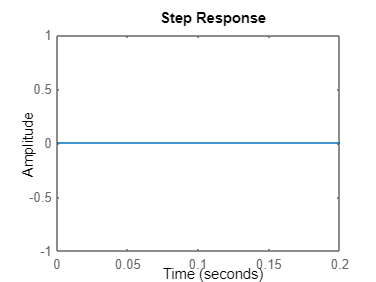

step(sys)